# Estimate Battery Model Parameters from HPPC Data

This example shows how to estimate the model parameters for a battery equivalent circuit model (ECM) from hybrid pulse power characterization (HPPC) data using Simscape™ Battery™. HPPC is a valuable technique in the battery industry and is one of the most common battery tests performed both at single-cell level or at system level. This technique involves applying a series of constant current pulses to a battery and measuring its terminal voltage and temperature responses at different operating conditions. There are multiple key operating conditions, including the initial battery soak temperature, initial state of charge (SOC), current or load, current directionality such as charge or discharge, state of health (SOH) or remaining capacity, and load frequency. The measured voltage response from each current pulse contains valuable information regarding the internal resistance or impedance of the battery. 

In this example, you first define an [HPPCTest](docid:battery_ref#mw_fd3d5bc9-9f99-4fac-be05-20abda753a8b) object that allows you to visualize, tabulate, and manipulate the different constant current pulses inside your HPPC data. The `HPPCTest` object contains a summary of all the current pulses performed in a single HPPC test program. This object automatically identifies each constant current pulse and tabulates it for inspection and preparation for the parameter estimation process as an optional data pre-processing step. This HPPC test data must be in a `MAT` file format and must contain time, current, and voltage signals. Optionally, you can specify the temperature, charge, and SOC.

You then estimate the parameters for a battery ECM that best match the terminal voltage response of the battery. The key outputs from the parameter estimation process are 1-D, 2-D, or 3-D parameter look-up tables. You can use these tables for control, as part of battery management system (BMS) algorithms, or for simulation, as parameters for the [Battery Equivalent Circuit](docid:battery_ref#mw_2e3c246d-9603-4fb8-9872-18301ef4d883) block. 

Finally, this example shows you how to automatically parameterize the Battery Equivalent Circuit block to run battery simulations.

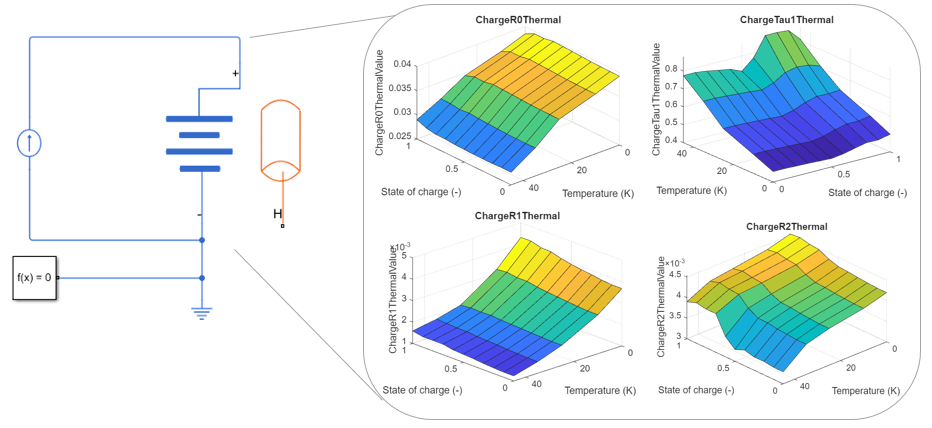 

## Create and Visualize `HPPCTest` Objects

An `HPPCTest` object automatically identifies all individual constant current pulses inside an HPPC test file. To create an `HPPCTest` object, first load the HPPC data into the MATLAB® workspace.

load("testDataBAKcells/hppcDataBAKcell25degC.mat","hppcData")

To create an `HPPCTest` object, use the `hppcTest` function. By default, the `HPPCTest` object assumes that the time, voltage, and current columns are named `"Time"`, `"Voltage"`, and `"Current"`, respectively. If these variables have different column name identifiers, you can specify them by using the optional name-value arguments. 

hppcExp25degC = hppcTest(hppcData,...
    TimeVariable="time (s)", ...
    VoltageVariable="voltage (V)", ...
    CurrentVariable="current (A)", ...
    Capacity=2.84, ...
    InitialSOC=0.055);

The `HPPCTest` object automatically calculates the battery SOC at every time step across the experiment, according to the input current measurement. The object use these calculated SOC values to define the SOC breakpoints for every constant current pulse. The `TestSummary` property contains a summary of these SOC breakpoints as well as all other temperature and current breakpoints identified from the data. Optionally, to improve the accuracy of the calculation of the SOC, the `hppcTest` function allows you to specify the battery capacity, the test initial SOC, and these column vectors:

- `Charge` — If you specify this column variable and the `StateOfCharge` variable is empty, the `HPPCTest` object uses the values in this column to calculate the SOC breakpoints. 

- `StateOfCharge` — if you specify this column variable, the `HPPCTest` object uses the values in this column to calculate the SOC breakpoints. 

 To visualize a summary of the test and the identified charge and discharge pulses, use the [plot](docid:battery_ref#mw_e6b68488-b1d7-4091-89e7-2b9389552f8c) function. 

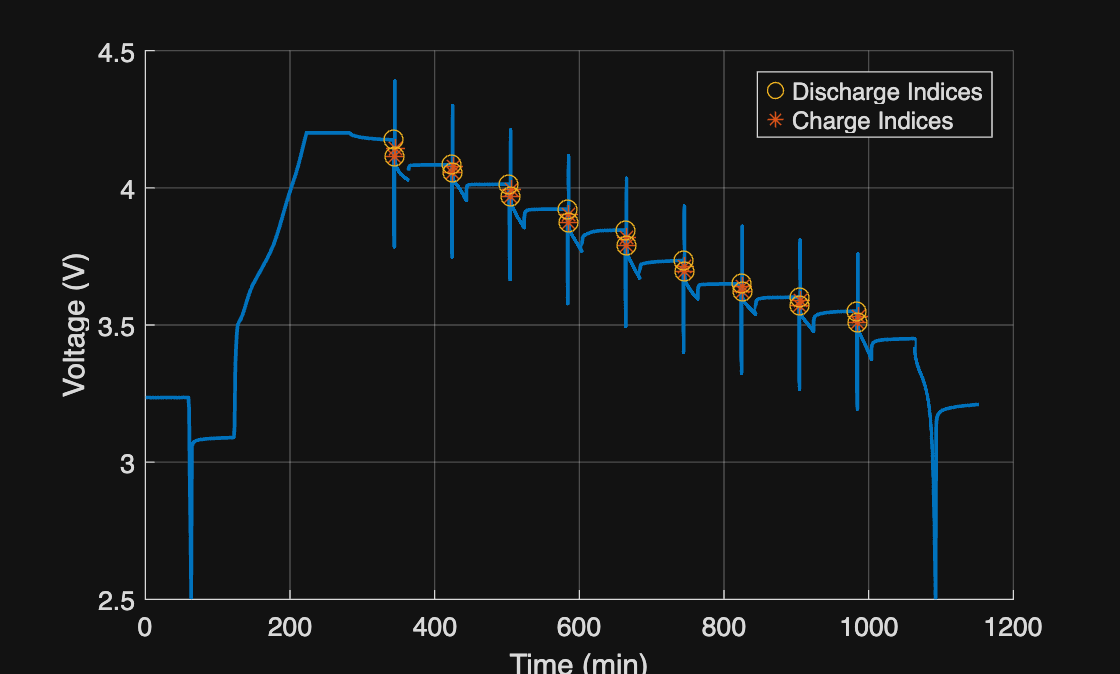

plot(hppcExp25degC)

The function automatically identifies the charge and discharge constant current pulses from the data according to these properties:

- `ValidPulseDurationRange` — Valid pulse duration range that indicates whether a pulse is valid and must be stored in the `TestSummary` property table. Decreasing the upper bound to values lower than 60 seconds ensures that very long discharges, such as capacity checks, are not included in the final list of pulses for estimation. Increasing the lower bound for this property to values greater than one or two seconds, ensures that the function excludes potential noise, outlier currents, or abnormally short pulses from the final list of pulses for estimation.  

- `ValidVoltageRange` — Valid battery voltage range that indicates whether a pulse is valid and must be stored in the `TestSummary` property table.

- `CurrentOnThreshold` — Threshold current value that indicates whether a charge or a discharge is occurring. This value is important for experiments where the rest or baseline current is not equal to zero.

- `NumSamplesRequirement` — Number of sequential points, specified as a scalar, at which the current must be greater than the `CurrentOnThreshold` value to signify the presence of a charge or discharge pulse.

You can customize these properties with your individual options to filter out or only select the pulses that you want to use for parameter estimation. Optionally, you can also remove pulses manually from the `TestSummary` table after object creation by using the [`removePulse`](docid:battery_ref#mw_934c5ea7-5f6a-471c-8933-fbc8efbe5afa) function.  

To view a summary of all the identified pulses, use the `TestSummary` property. 

disp(hppcExp25degC.TestSummary)

    PulseID    Directionality      SOC           HPPCData         PulseDuration    PseudoOCV_V    MaximumVoltage    MinimumVoltage    Current_A    C_rate    PulseStartIndex    PulseEndIndex    Temperature_degC
    _______    ______________    ________    _________________    _____________    ___________    ______________    ______________    _________    ______    _______________    _____________    ________________

       1        "Discharge"        0.9866    {701×6 timetable}         30            4.1745           4.1745            3.7846         -6

You can visualize the voltage response for specific pulses from the `TestSummary` table by using the [`plotPulse`](docid:battery_ref#mw_8622b4a7-471c-4cce-bfa1-7b8bed701f9d) function. The `plotPulse` function optionally accepts a second argument that specifies the index for the pulses to be visualized and inspected for abnormalities. This index refers to the `PulseID` column in the `TestSummary` property table. You can specify this index as a scalar or vector. 

Plot the first pulse in the `HPPCTest` object using the `plotPulse` function. 

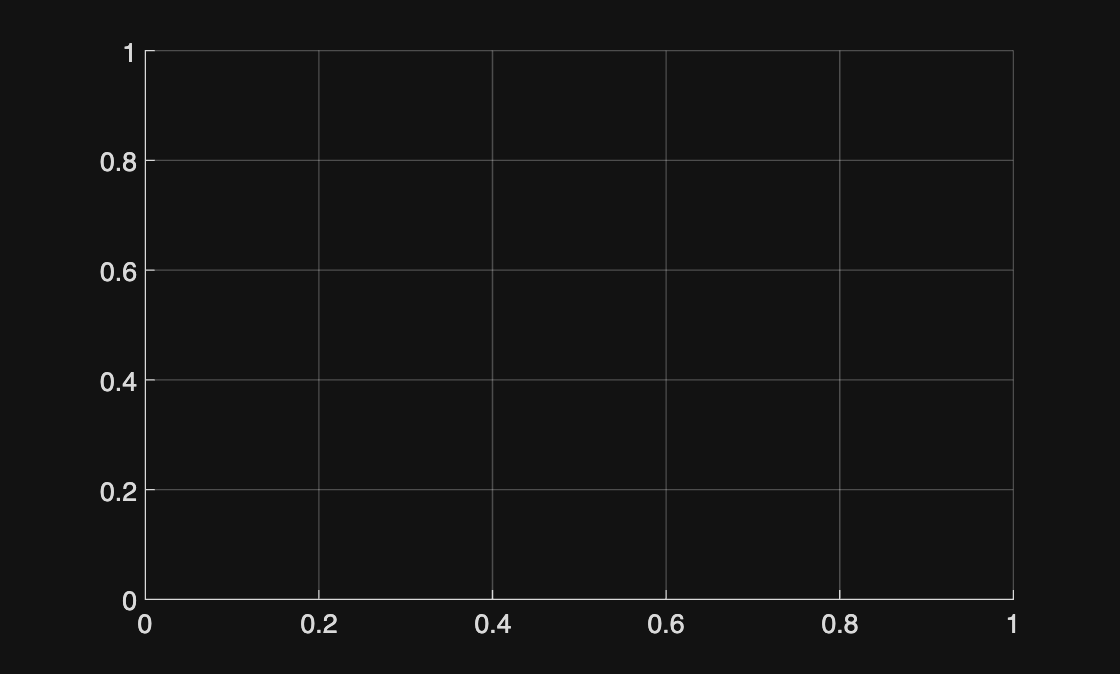

 plotPulse(hppcExp25degC)

This figure shows the different load and relaxation segments for a given constant current pulse. Typically, the battery ECM parameters are different depending on which segment you use for the parameter estimation process. 

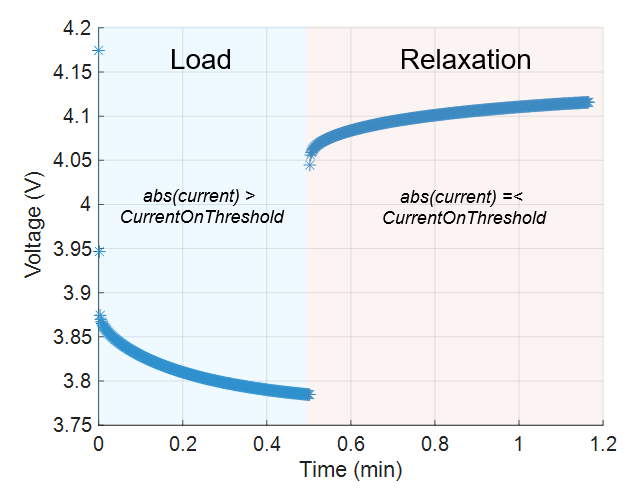

You can visualize the different pulses in a grid layout by defining a vector as the second argument of the `plotPulse` function.

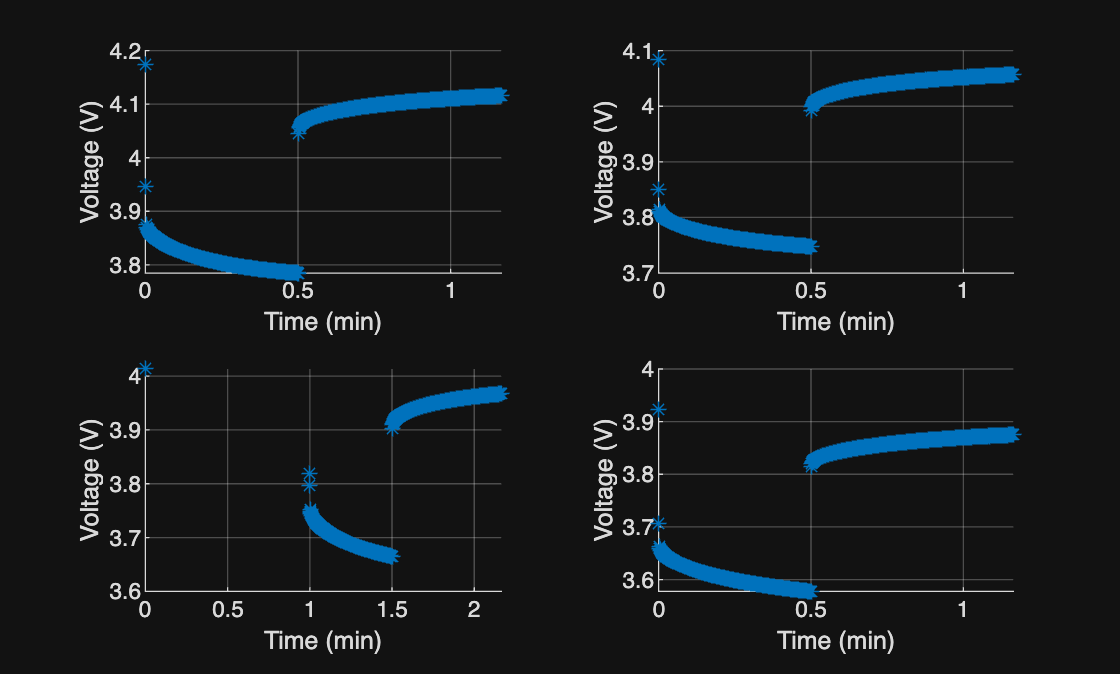

 plotPulse(hppcExp25degC,1:4)

You can also remove individual pulses that behave abnormally or do not meet your requirements, including nonlinear voltage response, missing points, voltage outliers, or abnormal dispersion. In this HPPC dataset, the third pulse might be missing the initial rest voltage at the beginning of the pulse. Remove it from the parameter estimation process by using the `removePulse` function. 

 removePulse(hppcExp25degC,3)

Inspect the updated `TestSummary` property. Notice that there are now only 17 pulses in the table. 

disp(hppcExp25degC.TestSummary) 

    PulseID    Directionality      SOC           HPPCData         PulseDuration    PseudoOCV_V    MaximumVoltage    MinimumVoltage    Current_A    C_rate    PulseStartIndex    PulseEndIndex    Temperature_degC
    _______    ______________    ________    _________________    _____________    ___________    ______________    ______________    _________    ______    _______________    _____________    ________________

       1        "Discharge"        0.9866    {701×6 timetable}         30            4.1745           4.1745            3.7846         -6

### Modify SOC breakpoints

If you do not have information about the battery capacity, SOC, or charge, you can optionally modify the SOC breakpoint values inside the `TestSummary` property table by using the [`setChargeSOCs`](docid:battery_ref#mw_f64673bb-57fd-4280-8f0f-c7eb371942fb) and [`setDischargeSOCs`](docid:battery_ref#mw_e43a686b-2647-4aad-8fb4-fd7d752f9477) functions. 

 setChargeSOCs(hppcExp25degC,[1,0.9,0.8,0.6,0.5,0.4,0.3,0.2,0.1]);
 setDischargeSOCs(hppcExp25degC,[1,0.9,0.7,0.5,0.4,0.3,0.2,0.1]);

Inspect the updated `TestSummary` property table. Notice that the functions modified the SOC breakpoints. 

disp(hppcExp25degC.TestSummary)

    PulseID    Directionality    SOC        HPPCData         PulseDuration    PseudoOCV_V    MaximumVoltage    MinimumVoltage    Current_A    C_rate    PulseStartIndex    PulseEndIndex    Temperature_degC
    _______    ______________    ___    _________________    _____________    ___________    ______________    ______________    _________    ______    _______________    _____________    ________________

       1        "Discharge"        1    {701×6 timetable}         30            4.1745           4.1745            3.7846         -6.1869     2.178

## Estimate Battery Model Parameters 

The process of parameter estimation involves minimizing the error between the predicted voltage output of the ECM and the measured battery voltage response from the HPPC test. This table shows the most typical ECMs used to represent the impedance of a battery:

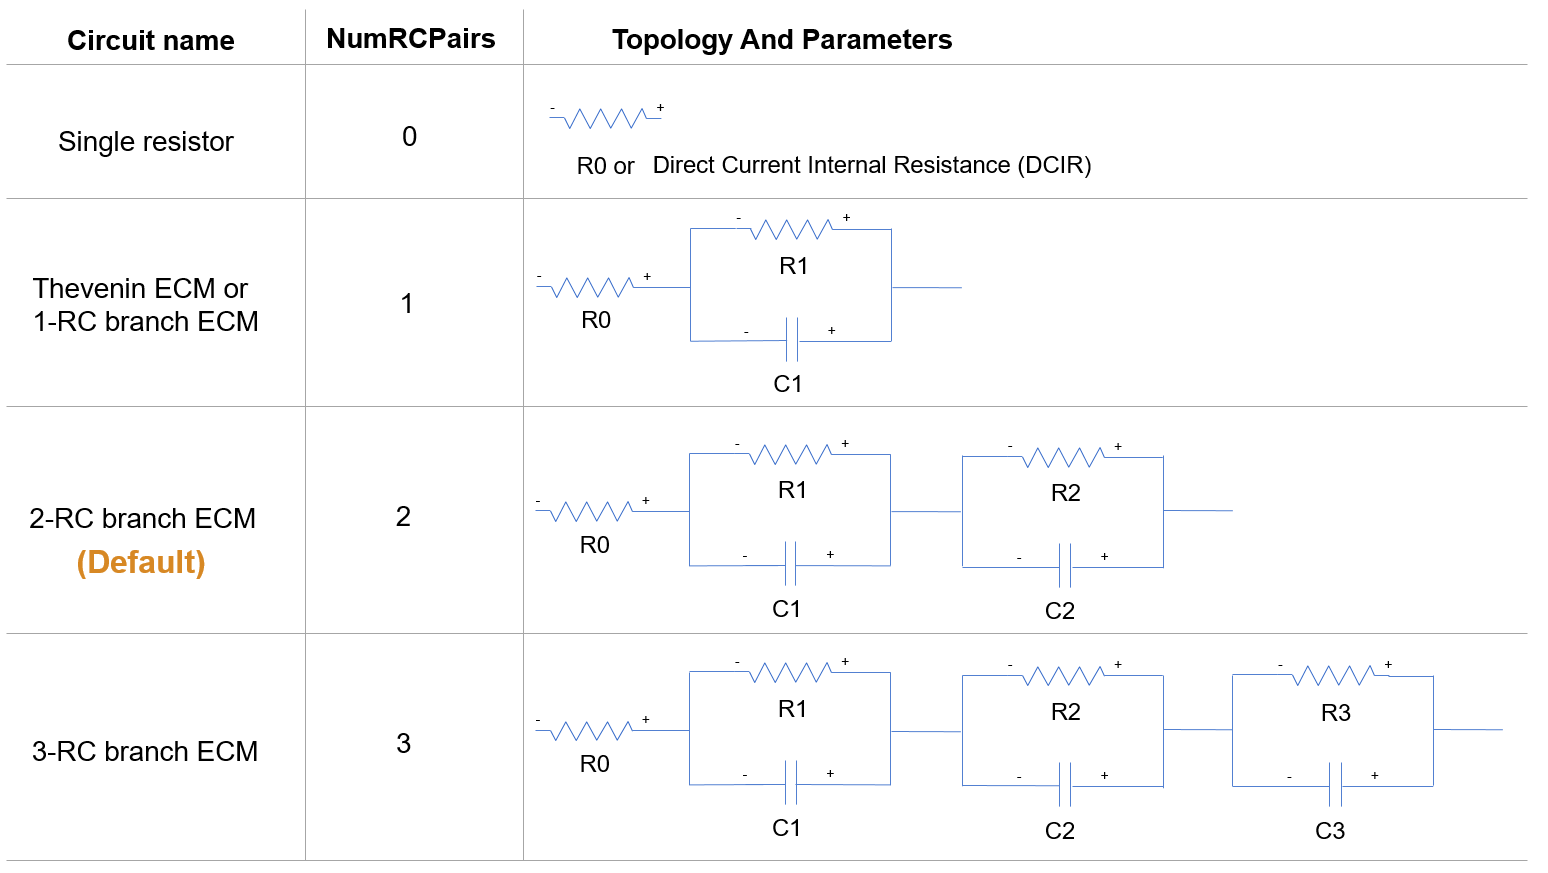

To minimize the error, you iteratively adjust the model parameters, such as `R0`, `R1`, and `C1`, until you achieve a satisfactory error between the measured voltage and a simulated voltage. There are several techniques in MATLAB that provide this functionality inside the Model-Based Calibration Toolbox™, System Identification Toolbox™, and Curve Fitting Toolbox™. In this example, you estimate the parameters of the battery model by using an optimization-based fitting method implemented in Simscape™ Battery™. This fitting method utilizes a custom implementation of the `fminsearch` function. 

The battery ECM parameters for a specific operating point can be different depending on which segment or section of the current pulse you use for the parameter estimation process. The load-segment parameters suit most applications. However, the best estimation segment depends on the specific end application of the battery ECM. Some methods are better suited to estimate parameters for a given segment, for example the System Identification Toolbox `tfest` function works best for fitting load-only dynamics. This table contains a summary of the supported options for the `FittingMethod` and `SegmentToFit` arguments of the [`fitECM`](docid:battery_ref#mw_8d7b9ebd-ee1e-4304-bd11-e1f7a282444f) function, depending on the chosen toolbox or method. 

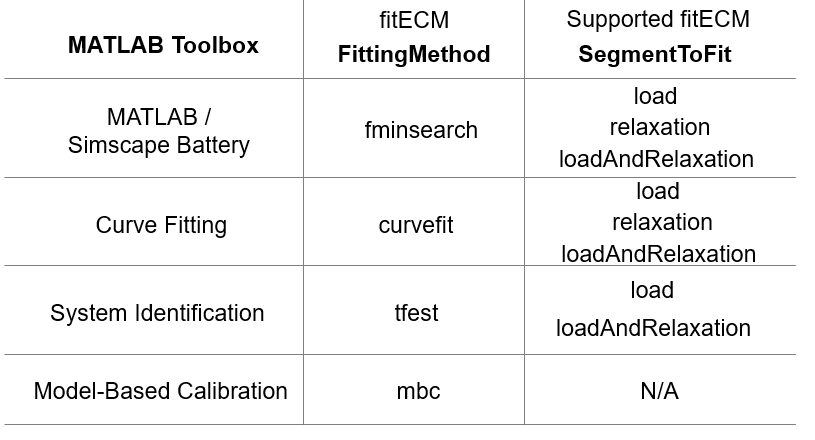

### Estimate Parameters for Single Current Pulse

There are a total of 17 constant current pulses inside the `hppcExp25degC` object. To estimate the ECM parameters for a specific constant current pulse profile in your test data, first define the index of the pulse you want to find the ECM parameters for. This index relates to a specific row in the `TestSummary` property table.

pulseIndex = 5;

To find the ECM parameters, use the `fitECM` function. This function requires the HPPC test data as input. The default value for the `FittingMethod` argument is `"fminsearch"`, which is the optimization method implemented in Simscape Battery. The default value for the `SegmentToFit` argument focuses on the relaxation section of the constant current pulse. Different options for the `FittingMethod` argument of the `fitECM` function allow you to perform the parameter estimation process for different segments of the pulse.

batteryEcm = fitECM(hppcExp25degC.TestSummary.HPPCData{pulseIndex}(:,1:2), SegmentToFit="loadAndRelaxation"); 

The `fitECM` function returns an [ECM](docid:battery_ref#mw_4a4d85e6-b7de-4aad-bfef-7d0c239563bb) object. View the ECM topology and other properties of the ECM object. 

disp(batteryEcm)

You can define optional name-value arguments for the `fitECM` function. For example, the `ECM` name-value argument specifies the desired ECM circuit topology you want to use to fit the data. If you do not specify this argument, the `fitECM` function uses this 2-RC branch ECM topology:

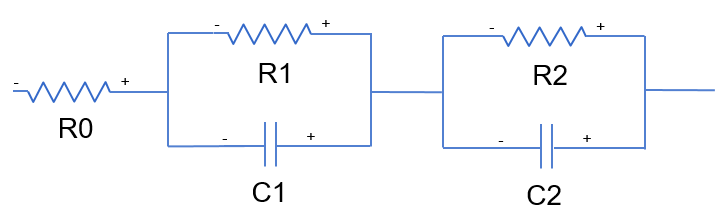

Use the [`plot`](docid:battery_ref#mw_ea10fd52-1563-4f35-8382-2c7d7057224d) function to visualize the measured and the simulated battery ECM voltage response. The plot function calculates the simulated battery ECM voltage response by assuming a constant open-circuit voltage value. In most cases, including a dynamic open-circuit voltage curve during the simulation improves the accuracy of the verification plot. 

 plot(batteryEcm)

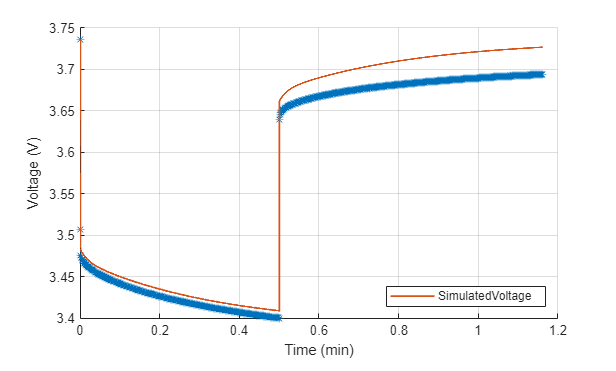

### Estimate Parameters for Sequence of Pulses

To estimate the ECM parameters for all the pulses inside a specific `HPPCTest` object, use the `fitECM` function and specify the entire `HPPCTest` object as input. 

batteryEcm = fitECM(hppcExp25degC, SegmentToFit="loadAndRelaxation"); 

Display the parameters and estimation error by using the `TestParameterTables` property of the `batteryEcm` object.

disp(batteryEcm.TestParameterTables)

The parameters inside the `TestParameterTables` property are different from the parameters inside the `ModelParameterTables` property. The `ECM` object determines the parameters inside the `ModelParameterTables` property by using the `ECM` object breakpoints you specify. The `ECM` object determines the parameters inside the `TestParameterTables` property by using the test conditions. View the model parameter tables by using the `ModelParameterTables` property. 

disp(batteryEcm.ModelParameterTables)

To view a complete summary of all the estimated parameter, use the `ParameterSummary` property of the `batteryECM` object. 

disp(batteryEcm.ParameterSummary)

To verify the accuracy of the fit for each specific current pulse, use the `plot` function. The `plot` function optionally accepts a second argument that specifies the index of the pulse fit that you want to visualize. This index refers to the `PulseID` column inside the `ParameterSummary` property table. You can specify this index as a scalar or a vector.

Plot the fit for the first four discharge pulses.

plot(batteryEcm,1:4)

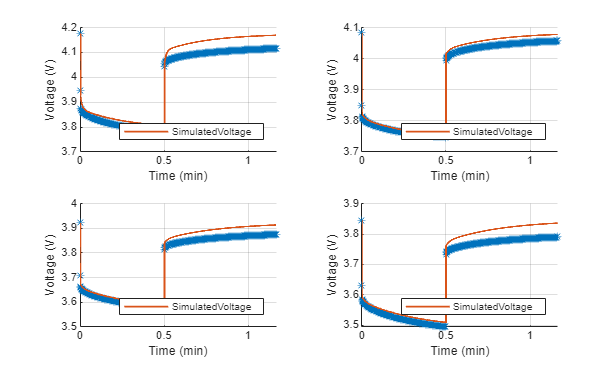

Plot the fit for the charge pulses 10, 11, 12, and 13.

plot(batteryEcm,10:13)

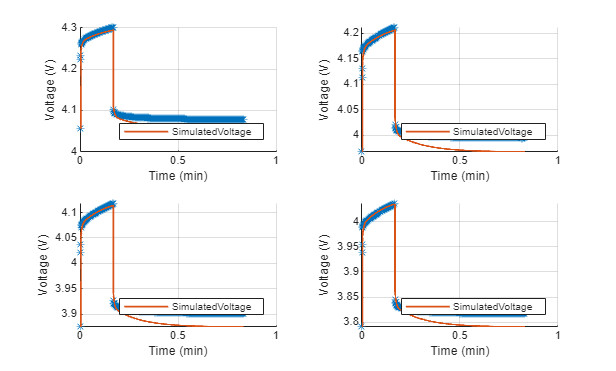

Once the you identify the ECM impedance parameters, to perform parameter verification, you can simulate the entire `HPPCTest`. The `fitECM` function only fits impedance and open-circuit voltage parameters in the data. If the test does not cover the full SOC range of a battery, the verification does not appear correct in these test areas. 

To verify the resulting model against the HPPC test data, select only the portion of the test that contains the pulses. 

data = hppcData((300:21475),:);
data.("time (s)") = data.("time (s)")-data.("time (s)")(1);
hppcExp25degCSim = hppcTest(data, ...
    TimeVariable="time (s)", ...
    VoltageVariable="voltage (V)", ...
    CurrentVariable="current (A)", ...
    Capacity=2.84, ...
    InitialSOC=1);

Visualize the model verification by using the [`simulateHPPCTest`](docid:battery_ref#mw_08732f9b-5586-4a46-a18c-f33923257b06) function.  

simulateHPPCTest(batteryEcm,hppcExp25degCSim)

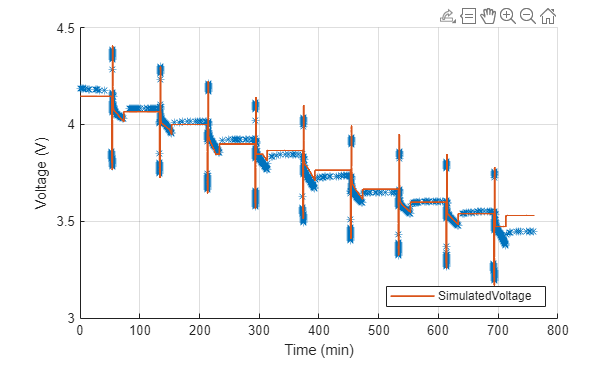

Alternatively, you can try different ECM topologies to achieve a better fit. Create an `ECM` object and specify the required number of parallel resistor-capacitor pairs. 

battery3RCECM = ecm(3);

To estimate the model parameters for this `ECM` object, use the `fitECM` function.

battery3RCECM = fitECM(hppcExp25degC,ECM=battery3RCECM, ...
    SegmentToFit="loadAndRelaxation"); 

To verify the accuracy of the fit for each specific current pulse, use the `plot` function.

plot(battery3RCECM,1:4)

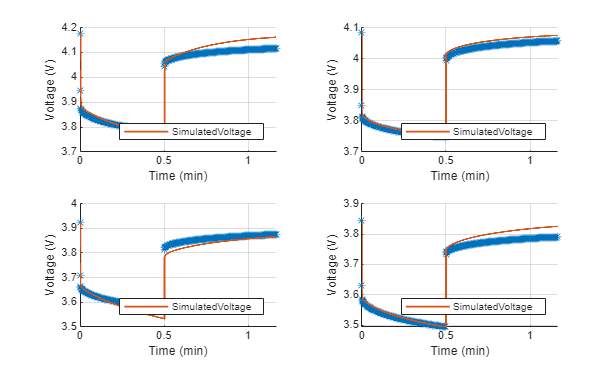

### Single Resistor or Direct Current Internal Resistance (DCIR) tables

The battery industry widely uses DCIR tables. Create an `ECM` object with no parallel resistor-capacitor pairs. This topology represents a single resistor.

batteryECMSingleRes = ecm(0);

Estimate the model parameters for this ECM by using the `fitECM` function.

batteryECMSingleRes = fitECM(hppcExp25degC,ECM=batteryECMSingleRes);

The ECM automatically populates with the DCIRs at different time frames depending on the pulse duration. The `fitECM` function uses these time frames: 2 seconds, 5 seconds, 10 seconds, 30 seconds, 60 seconds. For example, If the pulse duration is less than 60 seconds, the `fitECM` function does not include this DCIR value in the output table. 

To view all the DCIR tables, use the `TestParameterTables` property of the `batteryECMSingleRes` object.

disp(batteryECMSingleRes.TestParameterTables)

### Estimate Parameters for Suite of `HPPCTest` Objects

You can perform battery HPPC testing at many different conditions, including temperature, SOC, current, and remaining capacity. You can then store these tests in more than one file. Simscape™ Battery™ refers to several HPPC test files as a HPPC test suite. HPPC test suites are typically categorized depending on the battery temperature at the start of each current pulse, which remains constant across different SOC values and load currents. In other cases, the initial temperature of the battery can also vary inside a given test file depending on the test settings and thermal environment.

In Simscape™ Battery™, you can estimate multi-dimensional parameter tables for a suite of HPPC tests by merging different battery `ECM` objects or by using an [`HPPCTestSuite`](docid:battery_ref#mw_eda368e5-75e8-481b-8fae-bdd7b3011abc) object. 

### Merge Battery ECM Objects

You can perform parameter estimation for different `HPPCTest` objects at different temperatures, SOC values, or currents, and subsequently merge the resulting parameters into a single `ECM` object with a single set of multi-dimensional parameter tables. In this section, you estimate the ECM parameters for an HPPC test conducted at 0°C. First load the HPPC data. 

load("testDataBAKcells/hppcDataBAKcell0degC.mat")

Create the `HPPCTest` object by using the `hppcTest` function. 

hppcExp0degC = hppcTest( hppcData,... 
    TimeVariable="time (s)",...
    VoltageVariable="voltage (V)",...
    CurrentVariable="current (A)",...
    Temperature=zeros(numel(hppcData(:,1)),1));

Estimate the ECM parameters by using the `fitECM` function. 

batteryECM0degC = fitECM(hppcExp0degC, ...
    SegmentToFit="loadAndRelaxation");

The `batteryEcm` object you created before represents the ECM at 25°C. You can add or merge the 0 °C HPPC test parameters to the 25 °C model by using the [`mergeModelParameter`](docid:battery_ref#mw_14b2d35e-d658-4827-840d-db5b2139f4aa) function.

batteryEcm = mergeModelParameters(batteryEcm,batteryECM0degC);

Visualize the test parameter tables of the merged model. 

disp(batteryEcm.TestParameterTables)

Verify that the test breakpoints are 0°C and 25°C as expected. 

disp(batteryEcm.TestParameterTables.TestBreakpoints.ResistanceTemperatureBreakpoints)

Inspect the `ChargeR0Thermal` parameter values of the `TestParameterTables` property.

disp(batteryEcm.TestParameterTables.ChargeR0Thermal)

### Use `HPPCTestSuite` Objects

To estimate multi-dimensional parameter tables for a suite of HPPC tests, first load HPPC files for experiments conducted at 10 °C, 35 °C, and 45 °C, and then create different `HPPCTest` objects. 

load("testDataBAKcells/hppcDataBAKcell10degC.mat")
hppcExp10degC = hppcTest(hppcData, ...
    TimeVariable="time (s)", ...
    VoltageVariable="voltage (V)", ...
    CurrentVariable="current (A)", ...
    Temperature=repmat(10,numel(hppcData(:,1)),1));
load("testDataBAKcells/hppcDataBAKcell35degC.mat")
hppcExp35degC = hppcTest(hppcData, ...
    TimeVariable="time (s)", ...
    VoltageVariable="voltage (V)", ...
    CurrentVariable="current (A)", ...
    Temperature=repmat(35,numel(hppcData(:,1)),1));
load("testDataBAKcells/hppcDataBAKcell45degC.mat")
hppcExp45degC = hppcTest(hppcData, ...
    TimeVariable="time (s)", ...
    VoltageVariable="voltage (V)", ...
    CurrentVariable="current (A)", ...
    Temperature=repmat(45,numel(hppcData(:,1)),1));

To create an `HPPCTestSuite` object, use the `hppcTestSuite` function.

hppcSuite = hppcTestSuite([hppcExp0degC;hppcExp10degC;hppcExp25degC;hppcExp35degC;hppcExp45degC], ...
    Temperature=[0;10;25;35;45]);
disp(hppcSuite.SuiteSummary)

To estimate the model parameters for an `HPPCTestSuite` object with the default ECM, use the `fitECM` function.

batteryEcm = fitECM(hppcSuite);

The `fitECM` function estimates the parameters for each pulse and stores the resulting parameters in the `TestParameterTables` property. 

disp(batteryEcm.TestParameterTables)

These parameter tables can be different to the final model parameters that you use in Simscape Battery. The difference resides in the breakpoint properties that you specify for the `ECM` object. View the `ModelParameterTables` properties. 

disp(batteryEcm.ModelParameterTables)

You can manually change the resistance breakpoints by updating the `ResistanceTemperatureBreakpoints` property of the `batteryECM` object. 

batteryEcm.ResistanceTemperatureBreakpoints = simscape.Value([0,10,25,35,45]+273.15,"K");

 View the updated `ModelParameterTables` property. 

disp(batteryEcm.ModelParameterTables)

View the model parameters by using the [`plotModelParameters`](docid:battery_ref#mw_04bf1acd-4880-435a-ba54-0aa17a628fb1) function. 

batteryEcm.plotModelParameters();

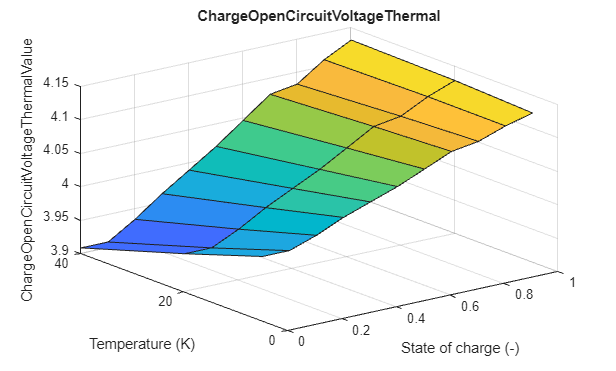

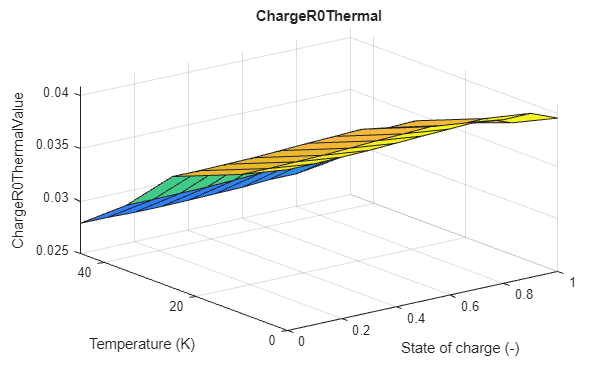

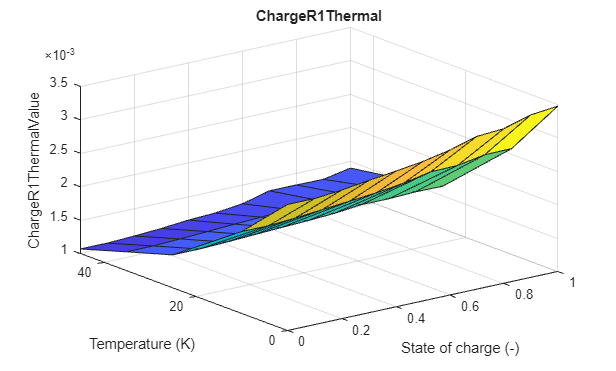

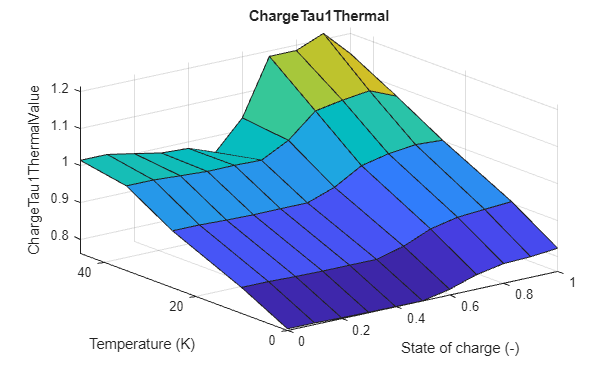

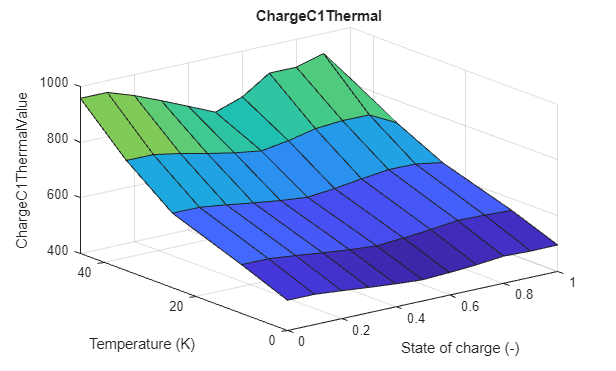

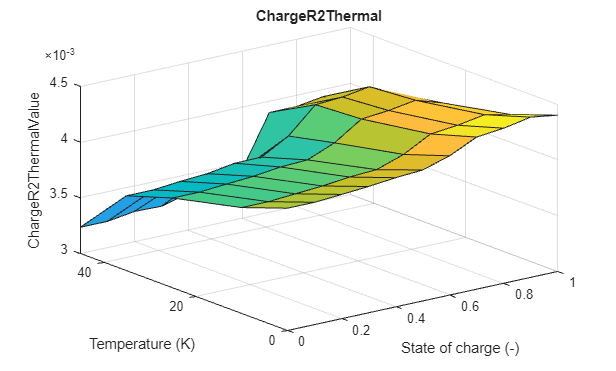

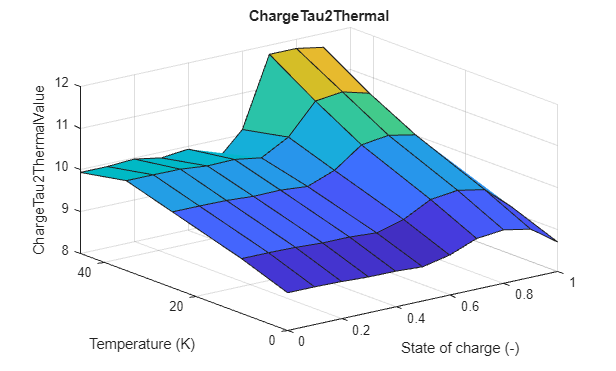

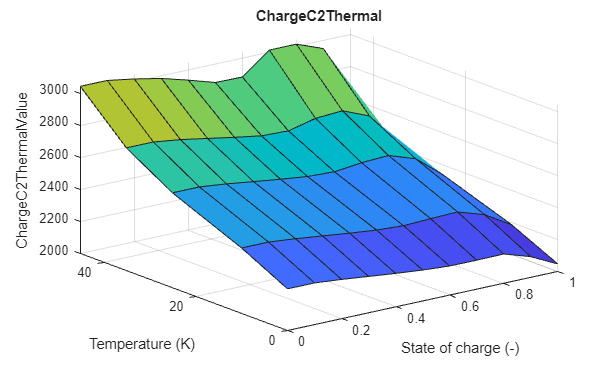

## Parameterize Battery Equivalent Circuit Block

You can parameterize the Battery Equivalent Circuit block as a final step in the parameterization workflow. This parameterization allows you to run battery simulations in Simulink®. To create a new Simulink battery model and add the Battery Equivalent Circuit block, use the `createBatteryModel` script.

if ~exist("batteryModel", 'file')
run("createBatteryModel.m")
end

Before parameterizing the block, you must obtain the block handle by using the [`getSimulinkBlockHandle`](docid:simulink_ref#bune5y3) function. 

batteryBlockHandle = getSimulinkBlockHandle('batteryModel/Battery01');

To automatically parameterize the Battery Equivalent Circuit block, use the [`parameterizeEquivalentCircuitBlock`](docid:battery_ref#mw_d4264263-e789-4692-a16f-8f0b74ac0483) function. 

batteryEcm.parameterizeEquivalentCircuitBlock(batteryBlockHandle,...
    ParameterizePseudoOCV=true)

Open the Battery Equivalent Circuit block mask to verify that the final model contains the correct parameter tables.

*Copyright 2024 The MathWorks, Inc.*